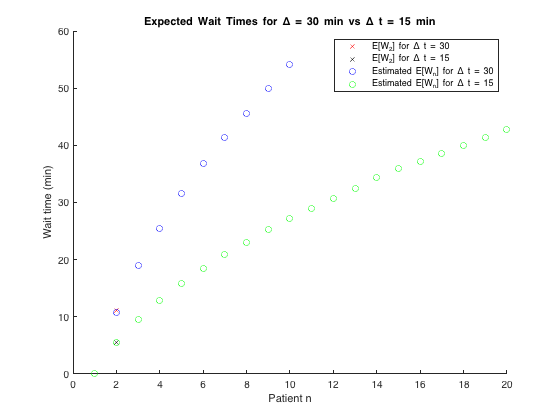

% Ben Juarez - PS4Q1bc

% Part b
delta_t1 = 30;
delta_t2 = 15;
n1 = 10;
n2 = 20;
N=10^4;
E_W1 = zeros(0,n1);
E_W2 = zeros(0,n2);
for i = 1:N
    W_n1 = zeros(1,n1);
    W_n2 = zeros(1,n2);
    for j = 1:n1
        if j == 1
            W_n1(j) = 0;
        else
            W_n1(j) = max(0, W_n1(j-1) + exprnd(delta_t1) - delta_t1);
        end
    end
    for j = 1:n2
        if j == 1
            W_n2(j) = 0;
        else
            W_n2(j) = max(0, W_n2(j-1) + exprnd(delta_t2) - delta_t2);
        end
    end
    E_W1 = [E_W1; W_n1];
    E_W2 = [E_W2; W_n2];
end
E_W1 = mean(E_W1);
E_W2 = mean(E_W2);

hold on
scatter(2, delta_t1 / exp(1), "X", "red")
scatter(2, delta_t2 / exp(1), "X", "black")
scatter(1:1:n1, E_W1, "o", "blue")
scatter(1:1:n2, E_W2, "o", "green")
legend("E[W_2] for \Delta t = 30", ...
    "E[W_2] for \Delta t = 15", ...
    "Estimated E[W_n] for \Delta t = 30", ...
    "Estimated E[W_n] for \Delta t = 15")
title("Expected Wait Times for \Delta = 30 min vs \Delta t = 15 min")
xlabel("Patient n")
ylabel("Wait time (min)")
hold off

% Part c
% We can see that the wait time is estimated to be lower for the 20th
% patient with delta t = 15 min (approx 43-44 min) compared to the 10th
% patient with delta t = 30 min (approx 53-54 min).  It is better to be
% be the 20th patient with delta t = 15 min!